Read test images.

img_lenna=imread("Lenna.jpg");
img_lenna=im2gray(img_lenna);
img_emu=imread("emu.jpg");
img_nene=imread("nene.jpg");
img_miku=imread("miku.jpg");
img_scene1=imread('scene1.jpg');
img_scene2=imread('scene2.jpg');

Inner function implementation.

% I1 = impyramid(img_lenna, 'reduce');
% I2 = impyramid(I1, 'reduce');
% I3 = impyramid(I2, 'reduce');
% figure, imshow(img_lenna)
% figure, imshow(I1)
% figure, imshow(I2)
% figure, imshow(I3)

Generate the image pyramid.

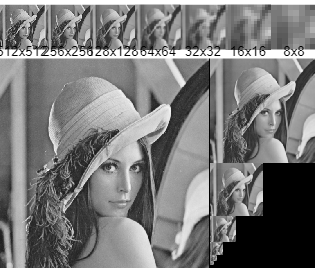

[g_pyramid,l_pyramid]=generate_pyramids(img_lenna);
display_image_pyramid(g_pyramid);

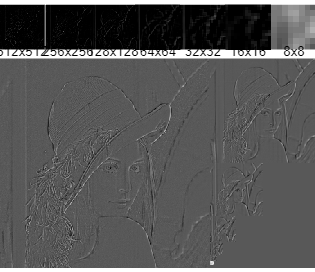

display_image_pyramid(l_pyramid);

Hybrid images (lowfreq-highfreq).

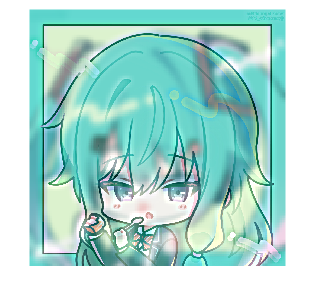

hybrid_miku_nene=hybrid_image(img_miku,flip(img_nene,2),4,'kernel_size',11,'sigma',5);
figure,imshow(hybrid_miku_nene);

Blend images (left-right).

blend_sc1_sc2=pyramid_blend_lr(img_scene1,img_scene2,'kernel_size',25,'sigma',5,'window',[0.45 0.55]);
figure,imshow(blend_sc1_sc2);

Blend images (mask).

mask1=zeros(size(img_scene1));
mask1(80:320,200:550,:)=1;
blendmask_sc1_sc2=pyramid_blend(img_scene1,img_scene2,mask1,'kernel_size',25,'sigma',5);
figure,imshow(blendmask_sc1_sc2);


Implement the functions manually.

function [g_pyramid,l_pyramid]=generate_pyramids(img,varargin)

    ip=inputParser;
    addParameter(ip, 'kernel_size', 5);
    addParameter(ip, 'sigma', 2);
    parse(ip,varargin{:});
    kernel_size=ip.Results.kernel_size;
    sigma=ip.Results.sigma;

    if class(img)=="uint8"
        img=double(img)/255.0;
    end

    [m,n,c]=size(img);
    max_n=ceil(log2(m)-3);
    g_pyramid={img};
    l_pyramid={};
    gaussian_kernel = fspecial('gaussian', [kernel_size kernel_size], sigma);
    for i=1:max_n        
        img_blur=imfilter(img,gaussian_kernel,"replicate","same","conv");
        % img_blur=imfilter(img,gaussian_kernel,"replicate");
        img_downsampled=imresize(img_blur,0.5,"nearest");
        upsample_size=size(img);
        upsample_size=upsample_size(1:2);
        img_upsampled=imresize(img_downsampled,upsample_size,"nearest");
        g_pyramid(i+1,:)={img_downsampled};
        l_pyramid(i,:)={img-img_upsampled};
        img=img_downsampled;
    end
    % disp(max_n+1);
    l_pyramid(max_n+1,:)={img};
end



function display_image_pyramid(imgs, varargin)

    ip=inputParser;
    addParameter(ip, 'margin', 2);
    parse(ip,varargin{:});
    margin=ip.Results.margin;

    N = size(imgs, 1);
    
    canvas = concatenate_image_pyramid(imgs, 'margin', margin);
    % figure, imshow(canvas);
    [ch,cw,~] = size(canvas);
    margin = margin / N / cw;
    pm = margin;
    figure;
    for i = 1:N
        % disp([pm 0.6 1/N 0.45])
        subplot('Position', [pm 0.8 1/N 0.2]);
        imshow(imgs{i},[]);
        text(0.5, -0.2, sprintf( '%dx%d', size(imgs{i},[1 2]) ), ...
             'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
             'FontSize', 10, 'Color', 'k', 'Units','normalized');

        pm = pm + 1/N + margin;
    end
    % disp(margin)
    subplot('Position', [margin margin 1-margin 0.8-margin]);
    imshow(canvas,[]);
    set(gcf, 'Position', [100, 100, cw, ch*1.3]);

end



function canvas=concatenate_image_pyramid(imgs,varargin)

    ip=inputParser;
    addParameter(ip, 'margin', 2);
    parse(ip,varargin{:});
    margin=ip.Results.margin;

    [m,n,c]=size(imgs{1});
    canvas=zeros([m ceil(n*1.5+margin) c]);
    canvas(1:m,1:n,1:c)=imgs{1};

    pm=1;
    pn=n+1+margin;
    for i=2:size(imgs,1)
        [m,n,c]=size(imgs{i});
        canvas(pm:pm+m-1,pn:pn+n-1,1:c)=imgs{i};
        pm=pm+m;
    end

end



function output = hybrid_image(img1, img2, N, varargin)
    
    ip=inputParser;
    addParameter(ip, 'kernel_size', 5);
    addParameter(ip, 'sigma', 2);
    parse(ip,varargin{:});
    kernel_size=ip.Results.kernel_size;
    sigma=ip.Results.sigma;

    % Step 1: 生成高斯和拉普拉斯金字塔
    [g_pyr1, l_pyr1] = generate_pyramids(img1, 'kernel_size',kernel_size,'sigma',sigma);
    [g_pyr2, l_pyr2] = generate_pyramids(img2, 'kernel_size',kernel_size,'sigma',sigma);
    
    % Step 2: 选择金字塔层次进行融合
    hybrid_pyr = cell(size(g_pyr1));
    
    % Step 3: 构建混合金字塔
    for i = 1:N-1
        hybrid_pyr{i} = l_pyr2{i}; % 使用第二幅图像的高频部分
    end
    for i = N:length(g_pyr1)
        hybrid_pyr{i} = g_pyr1{i}; % 使用第一幅图像的低频部分
    end
    % figure, imshow(concatenate_image_pyramid(hybrid_pyr));

    % Step 4: 重建混合图像
    output = rebuild_from_pyramid(hybrid_pyr,'N',N);

end



function output = pyramid_blend_lr(img1, img2, varargin)

    ip=inputParser;
    addParameter(ip, 'kernel_size', 5);
    addParameter(ip, 'sigma', 2);
    addParameter(ip, 'window', [0.3 0.7]);
    parse(ip,varargin{:});
    kernel_size=ip.Results.kernel_size;
    sigma=ip.Results.sigma;
    window=ip.Results.window;



    % Step 1: 生成 img1 和 img2 的高斯金字塔和拉普拉斯金字塔
    [g_pyr1, l_pyr1] = generate_pyramids(img1, 'kernel_size',kernel_size,'sigma',sigma);
    [g_pyr2, l_pyr2] = generate_pyramids(img2, 'kernel_size',kernel_size,'sigma',sigma);
    N=size(g_pyr1);

    % Step 2: 构建融合的拉普拉斯金字塔
    
    blend_pyr ={};
    for i = 1:N
        % 获取当前层的图像尺寸
        [m, n, c] = size(l_pyr1{i});
        start_point=round(n*window(1));
        stop_point=round(n*window(2));
        % 创建左右混合的权重矩阵（线性渐变）
        blend_weight = zeros(m, n);
        blend_weight(:, start_point:stop_point) = repmat(linspace(0, 1, stop_point-start_point+1), m, 1); % 过渡区域
        blend_weight(:, stop_point:n) = 1; % 右侧部分使用 img2
        if c > 1
            blend_weight = repmat(blend_weight, [1, 1, c]);
        end
        % figure,imshow(blend_weight);
        % 按权重进行融合
        blend_pyr(i,:) = { (1 - blend_weight) .* double(l_pyr1{i}) + blend_weight .* double(l_pyr2{i}) };
        % figure, imshow( (1 - blend_weight) .* double(l_pyr1{i}) )
        % figure, imshow( blend_weight .* double(l_pyr2{i}) )
        % figure, imshow(blend_pyr{i});
        
    end
    % figure, imshow(concatenate_image_pyramid(blend_pyr) ,[]);

    % Step 3: 从融合的金字塔中重建最终的图像
    output=rebuild_from_pyramid(blend_pyr);
    % show_images({img1, img2, output});
end

function output=rebuild_from_pyramid(pyr,varargin)

    ip=inputParser;
    addParameter(ip, 'N', size(pyr));
    parse(ip,varargin{:});
    N=ip.Results.N;
    
    % disp(N);
    output = pyr{N};
    for i = N-1:-1:1
        upscale_size=size(pyr{i});
        upscale_size=upscale_size(1:2);
        output = imresize(output, upscale_size, 'nearest') + pyr{i};
    end
    % disp(output);
    % figure, imshow(output);
end



function output = pyramid_blend(img1, img2, mask, varargin)

    ip=inputParser;
    addParameter(ip, 'kernel_size', 5);
    addParameter(ip, 'sigma', 2);
    parse(ip,varargin{:});
    kernel_size=ip.Results.kernel_size;
    sigma=ip.Results.sigma;

    % Step 1: 生成 img1, img2 和 mask 的高斯金字塔和拉普拉斯金字塔
    [g_pyr1, l_pyr1] = generate_pyramids(img1, 'kernel_size',kernel_size,'sigma',sigma);
    [g_pyr2, l_pyr2] = generate_pyramids(img2, 'kernel_size',kernel_size,'sigma',sigma);
    [g_mask_pyr l_mask_pyr]= generate_pyramids(mask, 'kernel_size',kernel_size,'sigma',sigma);
    N=size(g_pyr1,1);
    % disp(g_mask_pyr)
    % display_image_pyramid(g_pyr1);

    % Step 2: 构建融合的拉普拉斯金字塔
    blend_pyr = {};
    for i = 1:N
        % 融合拉普拉斯层，按掩模进行加权平均
        % disp({g_mask_pyr{i}, l_pyr1{i} } );
        blend_pyr(i,:) ={ g_mask_pyr{i}.*l_pyr1{i} + (1-g_mask_pyr{i}).*l_pyr2{i} };
    end
    % display_image_pyramid(blend_pyr);
    % disp(blend_pyr);

    % Step 3: 从融合的金字塔中重建最终的图像
    % disp(blend_pyr);
    output = rebuild_from_pyramid(blend_pyr);
    
    % 显示结果
    % show_images({img1 img2 mask output});
end



function show_images(imgs)
    % Display input list of images
    num_imgs = length(imgs); % Determine the number of images
    % Calculate suitable layout
    rows = ceil(sqrt(num_imgs)); % Determine the number of rows
    cols = ceil(num_imgs / rows); % Determine the number of columns
    figure;
    for i = 1:num_imgs
        subplot(rows, cols, i); % Create subplot
        imshow(imgs{i},'InitialMagnification','fit'); % Display image
        title(['Image ', num2str(i)]); % Add title
    end
end